# TP2: Respuesta en Frecuencia

22.93 Control Automático

Rocío Parra

2020

Para cada ejercicio, se propone diseñar un controlador propio con acción integral, y si fuese necesario redes de atraso o adelanto. Se debe conseguir un sobrepico menor al 10%, y el mejor ancho de banda de lazo cerrado posible.

En todo el trabajo, $T_s$ refiere al tiempo de sampleo, que se debe definir apropiadamente de manera tal que no se impida la estabilización. 

En todos los problemas deben graficarse:

a) Respuesta transitoria de salida al escalón de referencia más escalón en la perturbación de entrada.

b) Respuesta transitoria de la acción de control al escalón de referencia más escalón en la perturbación de entrada.

c) Respuestas en frecuencia, 𝐿(𝑠), 𝑆(𝑠) y 𝑇(𝑠), 𝑃𝑆(𝑠) y 𝐶𝑆(𝑠).

d) Justificar el diseño en base a separar 𝑃(𝑠)=𝑃𝑚𝑝(𝑠)*𝑃𝑎𝑝(𝑠).

e) Compensar con margen de fase de al menos 60∘. Buscar una combinación factible de 𝑇𝑠 con el mejor ancho de banda posible de lazo cerrado cumpliendo con este requerimiento.

## Ejercicio 7


$$P(s) = \frac{1}{2s^2} \cdot \frac{1}{s/80+1}\cdot \frac{1-s\cdot T_s/4}{1+s\cdot T_s/4}$$


Esta planta puede separarse intuitivamente en parte con fase mínima y parte pasa todo. Por comoidad en la simulación, se separa la parte pasa todo en lo que es parte de la simulación de tiempo discreto y otras partes pasa todo que pueda tener la planta, que en este caso no existen.


$$P_{mp}(s) = \frac{1}{2s^2} \cdot \frac{1}{s/80+1}, \quad P_{ap}(s) = \frac{1-s\cdot T_s/4}{1+s\cdot T_s/4}$$


ts = 1e-3;
s = tf('s');
p_mp = 1/(2*s^2)/(s/80+1);
pade = (1-s*ts/4)/(1+s*ts/4);
p_ap = 1;
planta = p_mp*p_ap*pade;
planta_disc = p_mp*p_ap;

En el controlador puede invertirse el polo en 1/80 y cancelar la constante 1/2, pero no es este el caso de los polos en el origen. Se propone, en cambio, incluir dos ceros complejos conjugados en el semiplano izquierdo, de manera tal que los polos del origen se "muevan" en esa dirección. 

Una vez considerada la acción integral, el controlador hasta ahora tendría 3 ceros y un polo. Por lo tanto, se incluyen además dos polos de alta frecuencia.

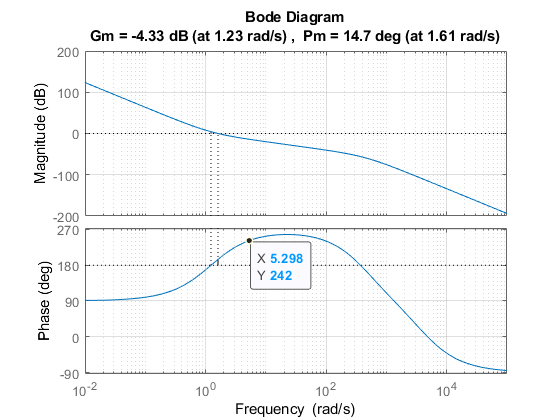

ki = 1;  % por ahora usamos este valor, luego se corregira

c_0 = ki/s; % accion integral
c_0 = c_0 * ((s/80)+1) * 2; % compensacion del polo en 1/80 y de la constante
c_0 = c_0 * (s+1) * (s+1.5); % compensacion de los polos en el origen
c_0 = c_0 / (s/450+1)^2; % controlador propio

L = planta*c_0;
margin(L);
grid on;
ax = gca;
chart = ax.Children(1).Children(1);
datatip(chart,5.298,242);

Del análisis de este gráfico se puede obtener que el mayor margen de fase está en 16.48rad/s, donde la magnitud vale (con ki=1) -26.13dB. Por lo tanto, se utilizará ki=+26.13dB.

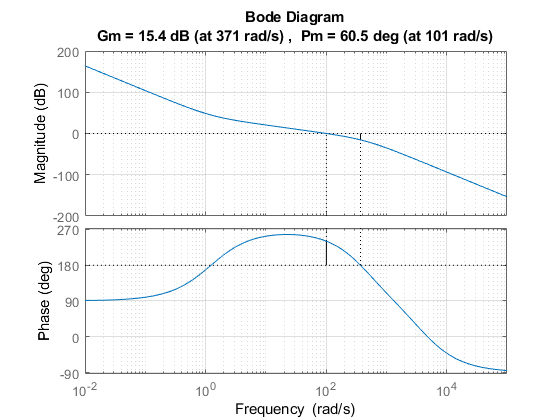

ki = db2mag(40.48);

% como antes ki=1, podemos simplemente multiplicar por la nueva ki 
c = ki*c_0; 
L = ki * L;

margin(L);
grid on;

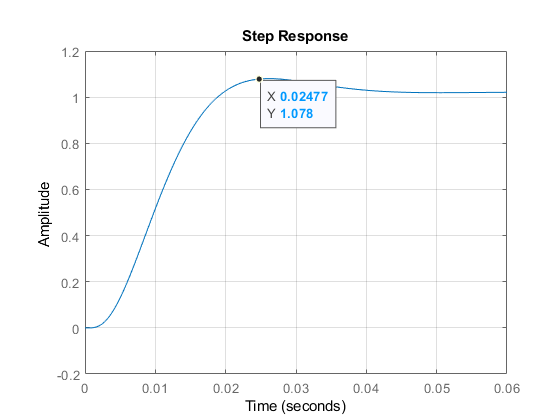

step(L/(1+L)); grid on;
ax3 = gca;
chart3 = ax3.Children(1).Children(2);
datatip(chart3,0.02477,1.078);

Como se esperaba, se tiene ahora un margen de fase satisfactorio, de 72.3 grados.

De este último gráfico se obtiene también la frecuencia de cruce, en 18.2rad/s.

w_cruce = 101;
alpha = w_cruce / (tan(w_cruce*ts/2));
opts = c2dOptions('PrewarpFrequency', alpha);
c_disc = c2d(c, ts, 'tutstin', opts);

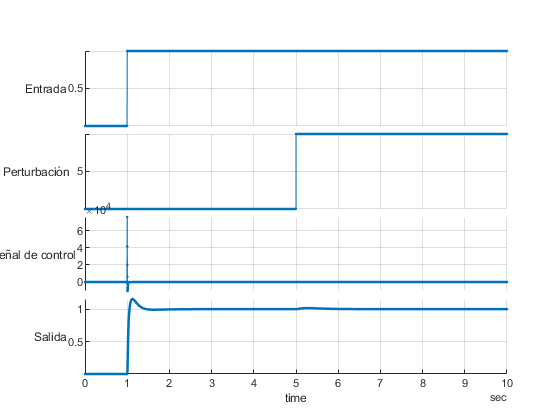

ctrlauto_plot2(7)

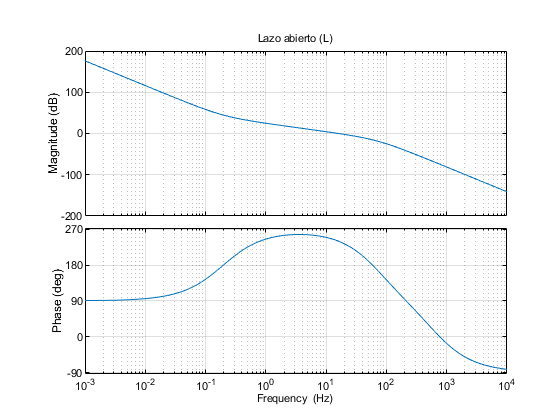

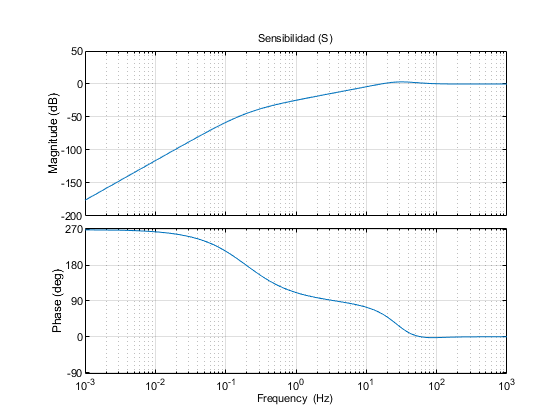

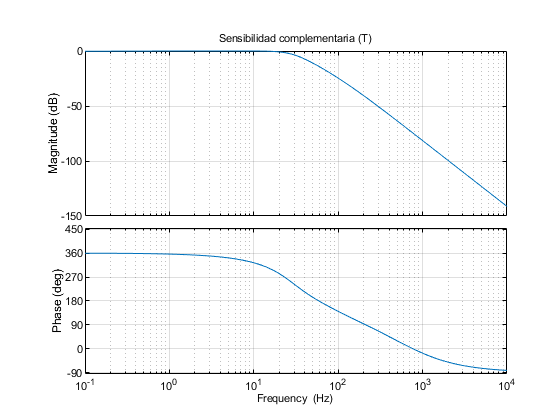

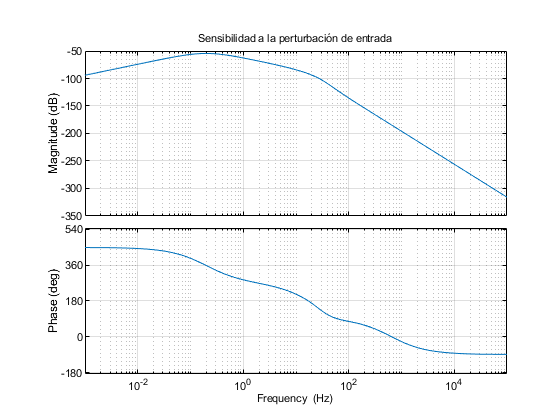

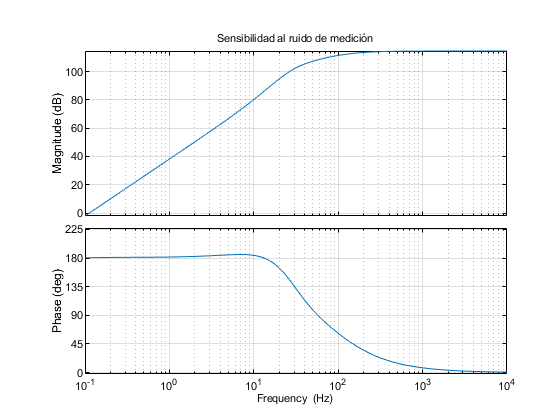

plots(planta, c)

## Ejercicio 8


$$P(s) = \frac{1}{s^2+4^2} \cdot \frac{1}{s/80+1}\cdot \frac{1-s\cdot T_s/4}{1+s\cdot T_s/4}$$


Nuevamente separamos entre fase mínima y pasa todo:


$$P_{mp}(s) = \frac{1}{s^2+4^2} \cdot \frac{1}{s/80+1}, \quad P_{ap}(s) = \frac{1-s\cdot T_s/4}{1+s\cdot T_s/4}$$


De manera similar al ejercicio anterior, podemos incluir en el controlador el polo en 1/80 como cero, pero no así los otros dos polos, dado que esto introduciría inestabilidad interna.

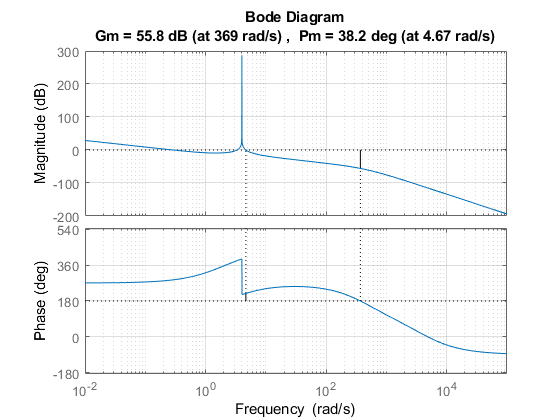

ts = 1e-3;
s = tf('s');
p_mp = 1/(s^2+4^2)/(s/80+1);
p_ap = (1-s*ts/4)/(1+s*ts/4);

ki = 1;  % por ahora usamos este valor, luego se corregira

c_0 = ki/s; % accion integral
c_0 = c_0 * ((s/80)+1); % compensacion del polo en 1/80
c_0 = c_0 * (s+3) * (s+1.5); % compensacion de los polos del eje jw
c_0 = c_0 / (s/450+1) / (s/450+1); % controlador propio

L=p_ap*p_mp*c_0;
figure(); margin(L); grid on;

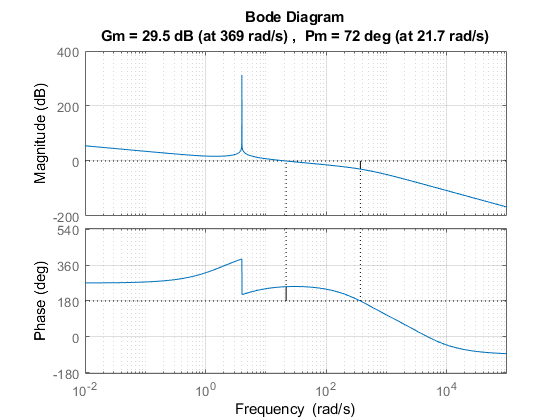


ki = db2mag(26.35);

% como antes ki=1, podemos simplemente multiplicar por la nueva ki 
c = ki*c_0; 
L = ki * L;

margin(L);
grid on;

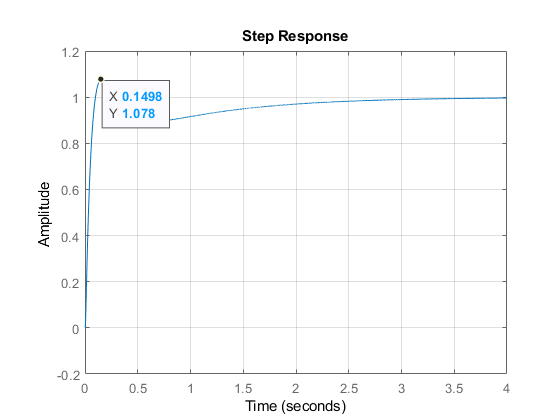

step(L/(1+L)); grid on;
ax4 = gca;
chart4 = ax4.Children(1).Children(2);
datatip(chart4,0.1494,1.078);

w_cruce = 21.7;
alpha = w_cruce / (tan(w_cruce*ts/2));
opts = c2dOptions('PrewarpFrequency', alpha);
c_disc = c2d(c, ts, 'tutstin', opts);

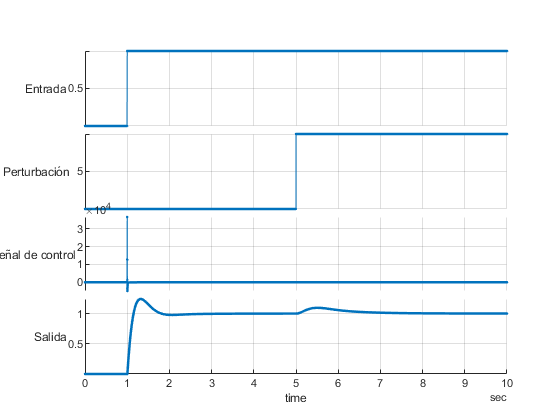

ctrlauto_plot2(8)

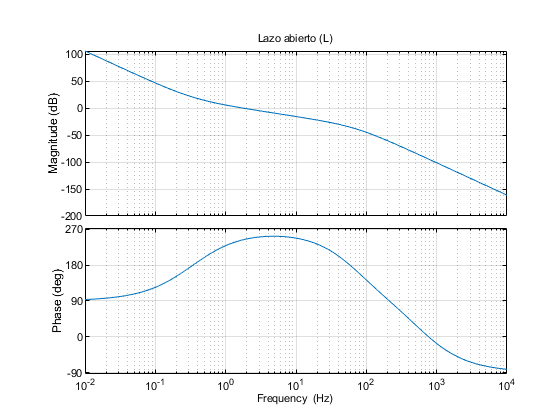

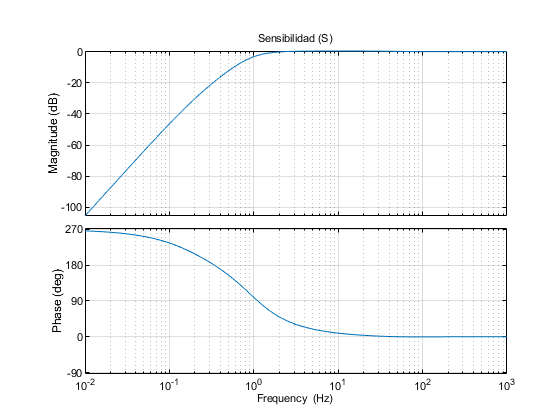

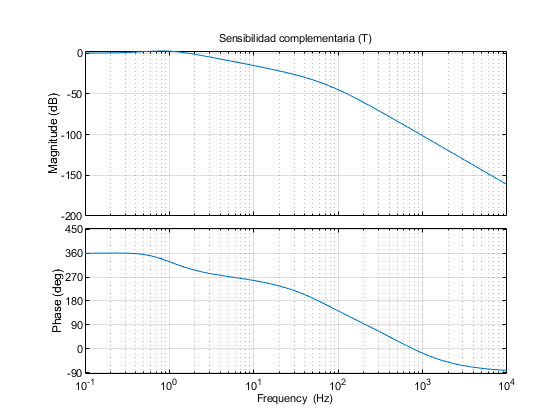

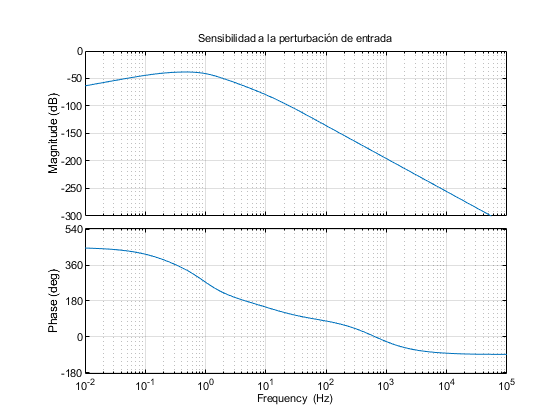

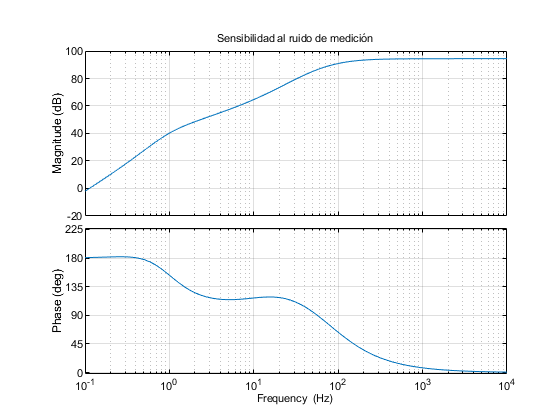

plots(planta, c)

## Ejercicio 9


$$P(s) = \frac{1}{s^2-4^2} \cdot \frac{1}{s/80+1}\cdot \frac{1-s\cdot T_s/4}{1+s\cdot T_s/4}$$


En este caso, se multiplica y divide por $s^2+4^2$ para obtener una parte de fase mínima

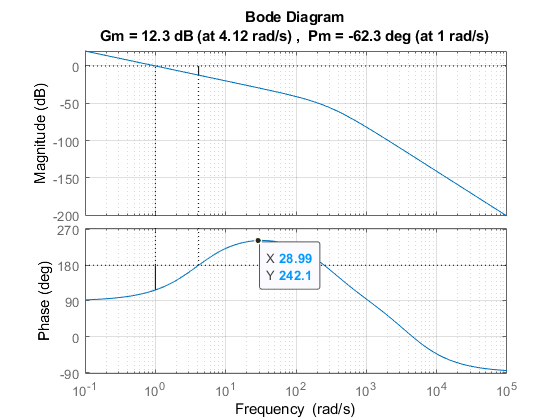

ts = 1e-3;
s = tf('s');
p_mp = 1/(s+4)^2/(s/80+1);
p_ap = (s+4)/(s-4) * (1-s*ts/4)/(1+s*ts/4);

ki = 1;  % por ahora usamos este valor, luego se corregira

c_0 = ki/s; % accion integral
c_0 = c_0 / p_mp; % compensacion del polo en 1/80 y los polos en 4
c_0 = c_0 / (s/250+1) / (s/350+1); % controlador propio

L = c_0 * p_mp * p_ap;
figure(); margin(L); grid on;

ax2 = gca;
chart2 = ax2.Children(1).Children(1);
datatip(chart2,28.15,240.2);

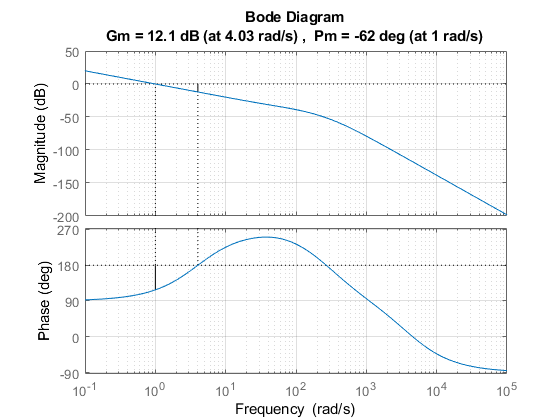

c_0 = c_0 * (s/50+1) / (s/70+1);
L = c_0 * p_ap*p_mp;
margin(L);
grid on;

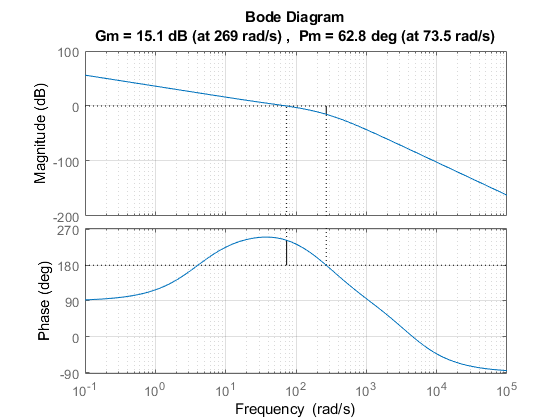

% ax3 = gca;
% chart3 = ax3.Children(1).Children(1);
% datatip(chart3,26.96,240.7);
ki = db2mag(36.1);
c = ki * c_0;
L = ki * L;

margin(L);
grid on;

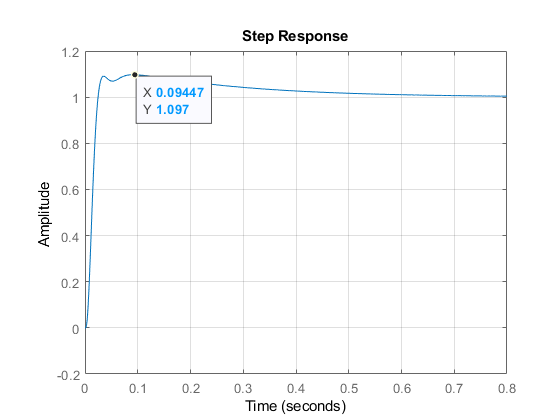


step(L/(1+L));
grid on;
ax5 = gca;
chart5 = ax5.Children(1).Children(2);
datatip(chart5,0.09447,1.097);


w_cruce = 73.5;
alpha = w_cruce / (tan(w_cruce*ts/2));
opts = c2dOptions('PrewarpFrequency', alpha);
c_disc = c2d(c, ts, 'tutstin', opts);

ctrlauto_plot2(9)

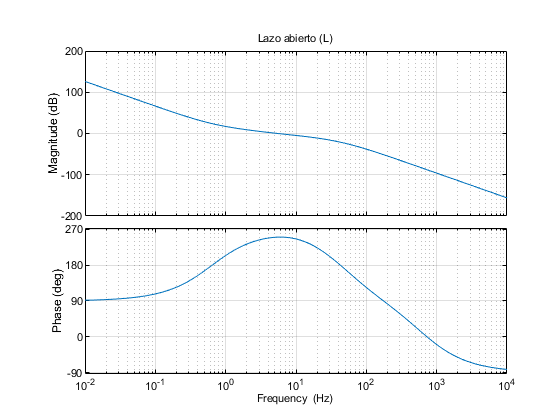

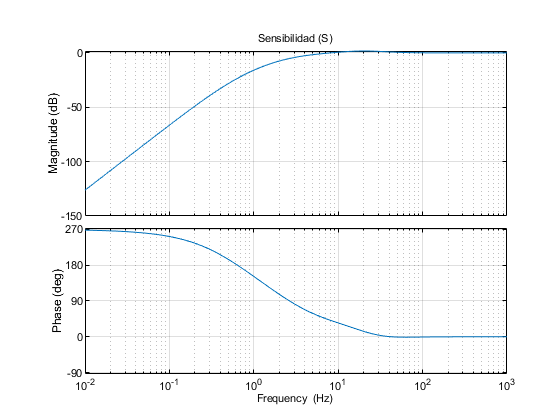

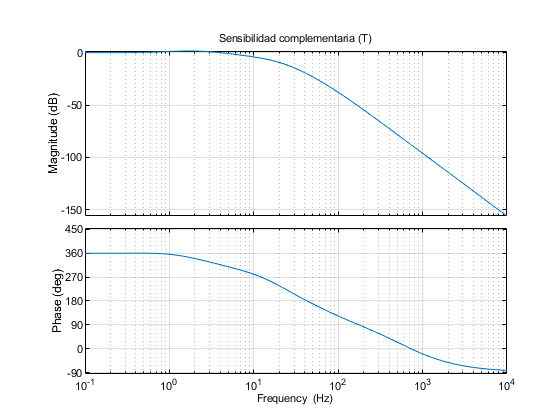

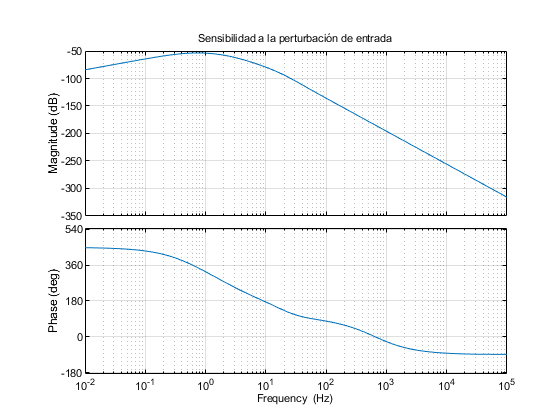

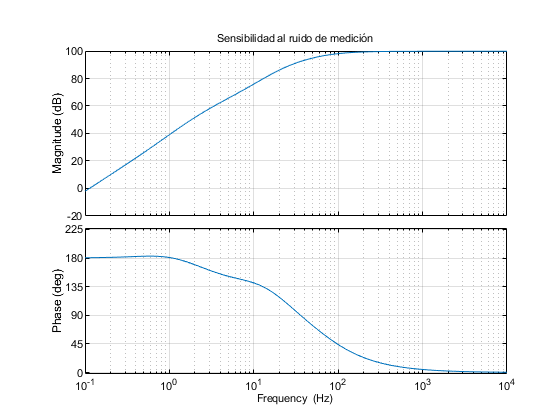

plots(planta, c)